clear
close all
clc
seed = 1234

seed = 1234

rng(seed)

FNT_SZ = 16;

%% Set the LPA parameters

% maximum degree of polynomial used for fitting
N = 1;

% parameter for the confidence intervals in the ICI rule
Gamma = 2;

% Set all the scale values
hmax = 51;
all_h = 1:hmax;

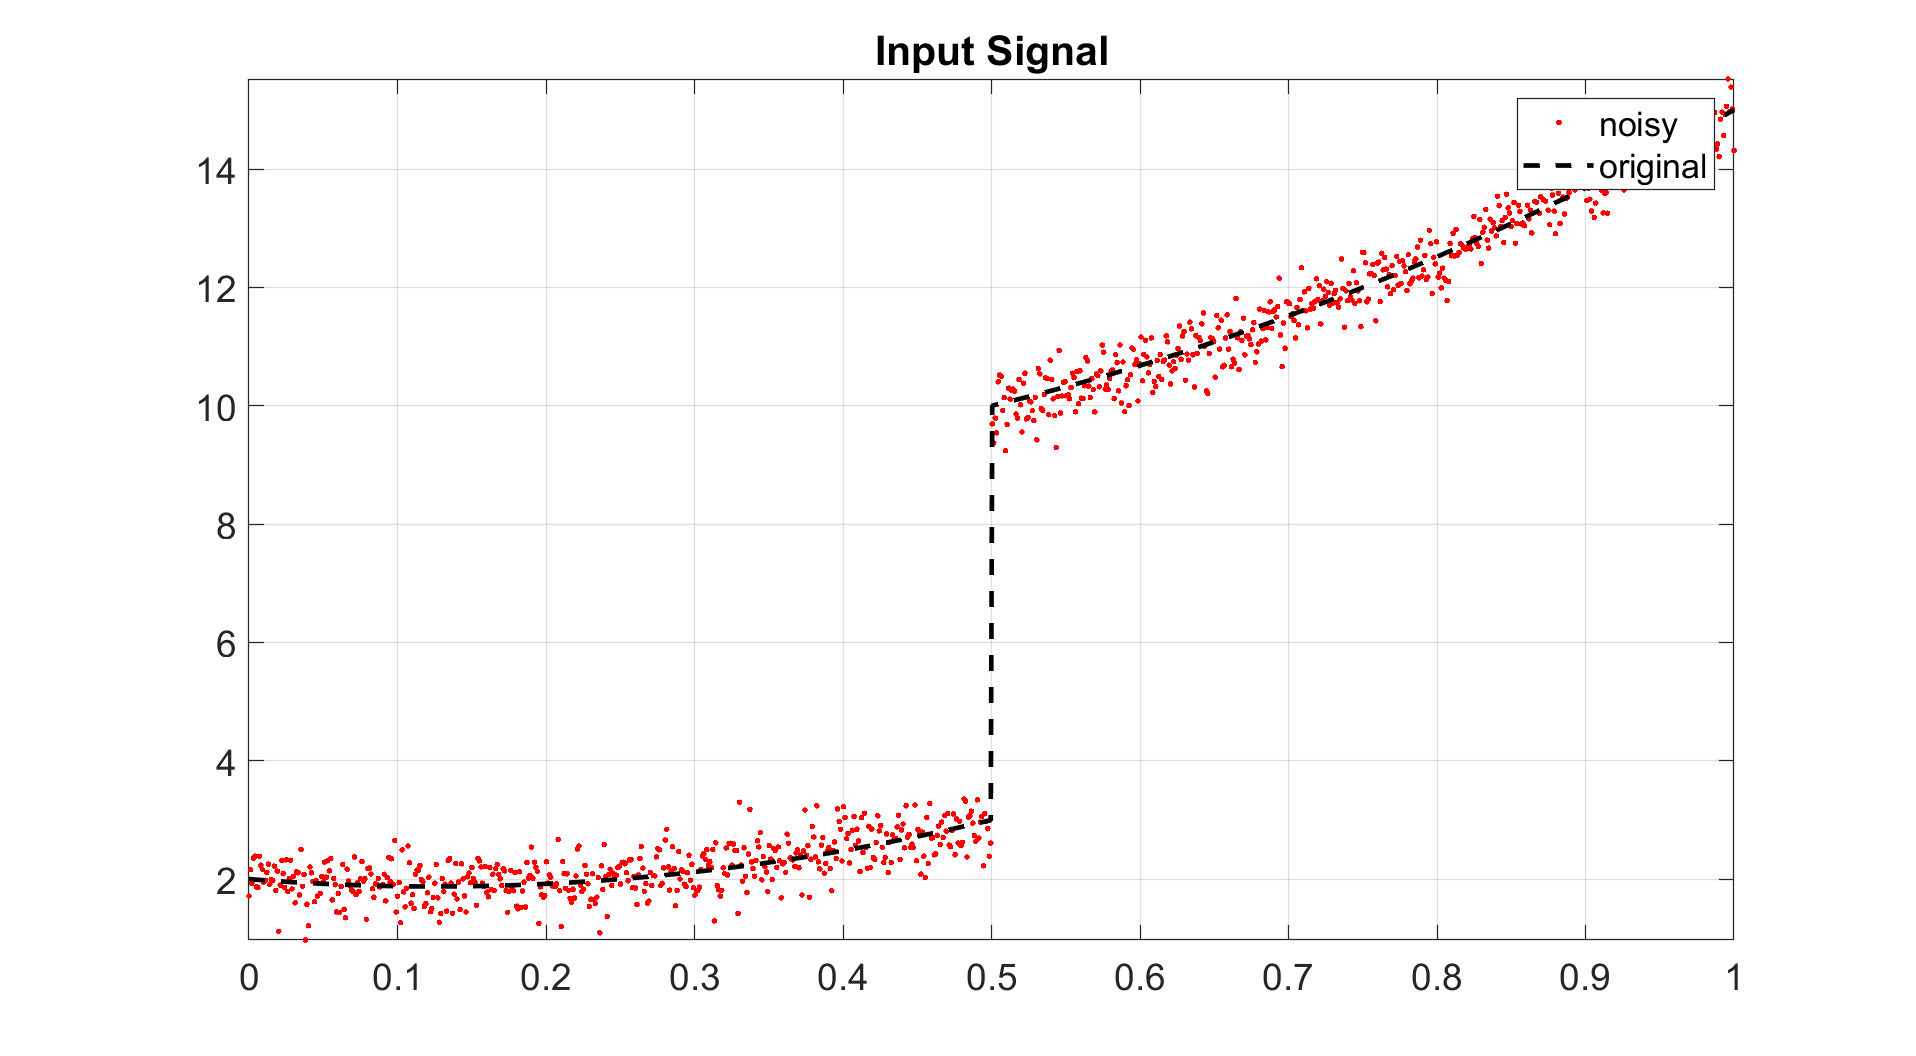

%% Generate Signal

% Generate the entire signal
LENGTH = 1000;
[y, ty] = get_synthetic_signal('parabolas', LENGTH);

% noise standard deviation
sigma = 0.3;

% noisy signal 
s = y + sigma*randn(size(y));

figure(1), 
plot(ty, s, 'r.');
hold on
plot(ty, y, 'k--', 'LineWidth', 2);
hold off
grid on
axis tight
set(gca,'FontSize', FNT_SZ)
legend('noisy', 'original');
title('Input Signal')
set(gcf, 'Position', [ 103 1 1574 867])

%% generate the LPA kernels for all the scale for both left and right windows

all_g_left = cell(length(all_h),1);
all_g_right = cell(length(all_h),1);
for ii=1:length(all_h)
    h = all_h(ii);
    
    % define the weights for the scale h (left)
    w = zeros(2*h-1, 1);
    HFS = floor(size(w,1) / 2);
    wl = w;
    wl(1 : HFS + 1) = 1;
    
    % compute and store the kernel g_left
    
    % TODO: implement the function compute_LPA_kernel
    g_left = compute_LPA_kernel(wl, N, ty);
    all_g_left{ii} = g_left;
    
    % define the weights for the scale h (right)
    wr = w;
    wr(HFS + 1 : end) = 1;    
    % compute and store the kernel g_right
    
    % TODO: implement the function compute_LPA_kernel
    g_right = compute_LPA_kernel(wr, N, ty);
    
    all_g_right{ii} = g_right;
end

%% right estimates
% find the best scale for each sample using the LPA-ICI rule

% initialize the right estimates for each scale
all_shat_right = zeros(size(all_h,2), LENGTH);

% initialize the vector containing the best scale for each sample
best_scale_right = zeros(1,LENGTH);

% initialize the lower and upper bound vectors
lower_bounds = -ones(1, LENGTH)*Inf;
upper_bounds = ones(1, LENGTH)*Inf;

% loop over all the scales
for ii=1:length(all_h)
    
    h = all_h(ii);
    g = all_g_right{ii};
    
    % compute the estimate for the scale h
    shat = conv(s, g, "same");
    
    % store the computed estimate
    all_shat_right(ii, :) = shat';
    
    % compute the lower and upper bound of the confidence interval for scale h
    lb = shat' - Gamma*sigma*norm(g, 2);
    ub = shat' + Gamma*sigma*norm(g, 2);

    % update the lower and upper bounds 
    lower_bounds = max(lower_bounds, lb);
    upper_bounds = min(upper_bounds, ub); 
    
    % identify for which samples h is the best scale according to the
    % ICI rule and update the best_scale vector accordingly
    idx = find((upper_bounds < lower_bounds) .* (best_scale_right==0));
    if ~isempty(idx)
        best_scale_right(idx) = h-1;
    end
end

idx = find(best_scale_right==0);
if ~isempty(idx)
    best_scale_right(idx) = h;
end

% use the best scale for each sample to compute the final right estimates
s_right= zeros(LENGTH,1);
for n=1:LENGTH
   best_h = best_scale_right(n);
   s_right(n) = all_shat_right(best_h, n);
end

%% left estimates
% find the best scale for each sample using the LPA-ICI rule

% initialize the left estimates for each scale
all_shat_left= zeros(size(all_h, 2), LENGTH);

% initialize the vector containing the best scale for each sample
best_scale_left= zeros(1, LENGTH);

% initialize the lower and upper bound vectors
lower_bounds = -ones(1, LENGTH)*Inf;
upper_bounds = ones(1, LENGTH)*Inf;

% loop over all the scales
for ii=1:length(all_h)
    
    h = all_h(ii);
    g = all_g_left{ii};
    
    % compute the estimate for the scale h
    shat = conv(s, g, "same");
    
    % store the computed estimate
    all_shat_left(ii, :) = shat';
    
    % compute the lower and upper bound of the confidence interval for scale h
    lb = shat' - Gamma*sigma*norm(g, 2);
    ub = shat' + Gamma*sigma*norm(g, 2);

    % update the lower and upper bounds 
    lower_bounds = max(lower_bounds, lb);
    upper_bounds = min(upper_bounds, ub); 
    
    % identify for which samples h is the best scale according to the
    % ICI rule and update the best_scale vector accordingly
    idx = find((upper_bounds < lower_bounds) .* (best_scale_left==0));
    if ~isempty(idx)
        best_scale_left(idx) = h-1;
    end
end
idx = find(best_scale_left==0);
if ~isempty(idx)
    best_scale_left(idx) = h;
end

% use the best scale for each sample to compute the final right estimates
s_left= zeros(LENGTH,1);
for n=1:LENGTH
   best_h = best_scale_left(n);
   s_left(n) = all_shat_left(best_h, n);
end

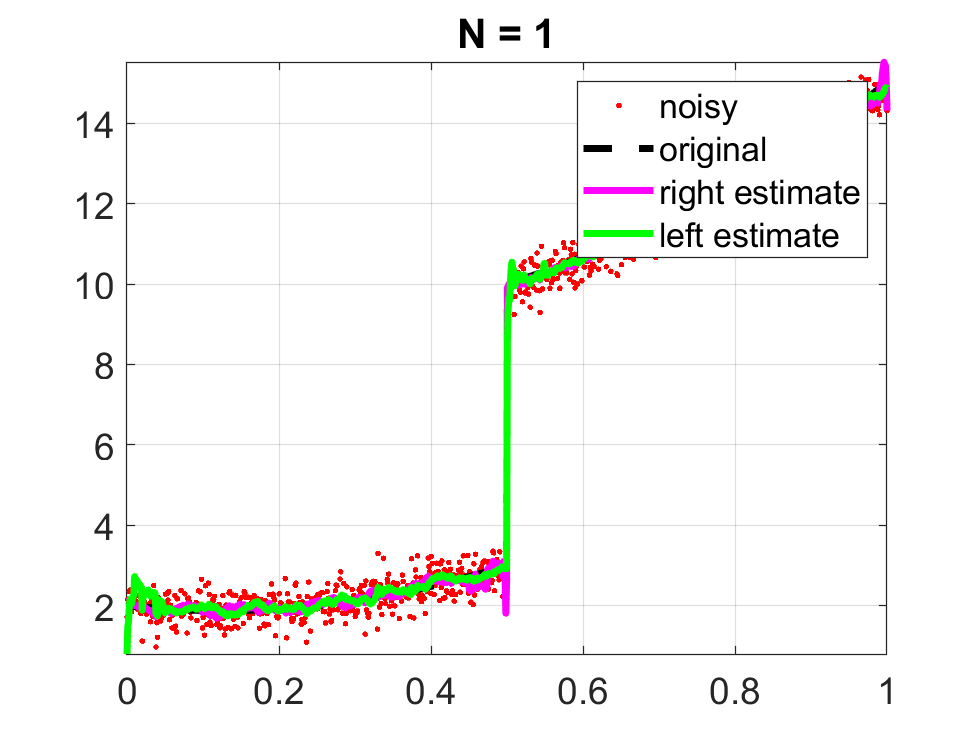


figure(2), 
plot(ty, s, 'r.');
hold on
plot(ty, y, 'k--', 'LineWidth', 3);
plot(ty, s_right, 'm-','LineWidth', 3);
plot(ty, s_left, 'g-','LineWidth', 3);
hold off
grid on
axis tight
title(['N = ', num2str(N)])
set(gca,'FontSize', FNT_SZ)
legend('noisy', 'original', 'right estimate', 'left estimate');

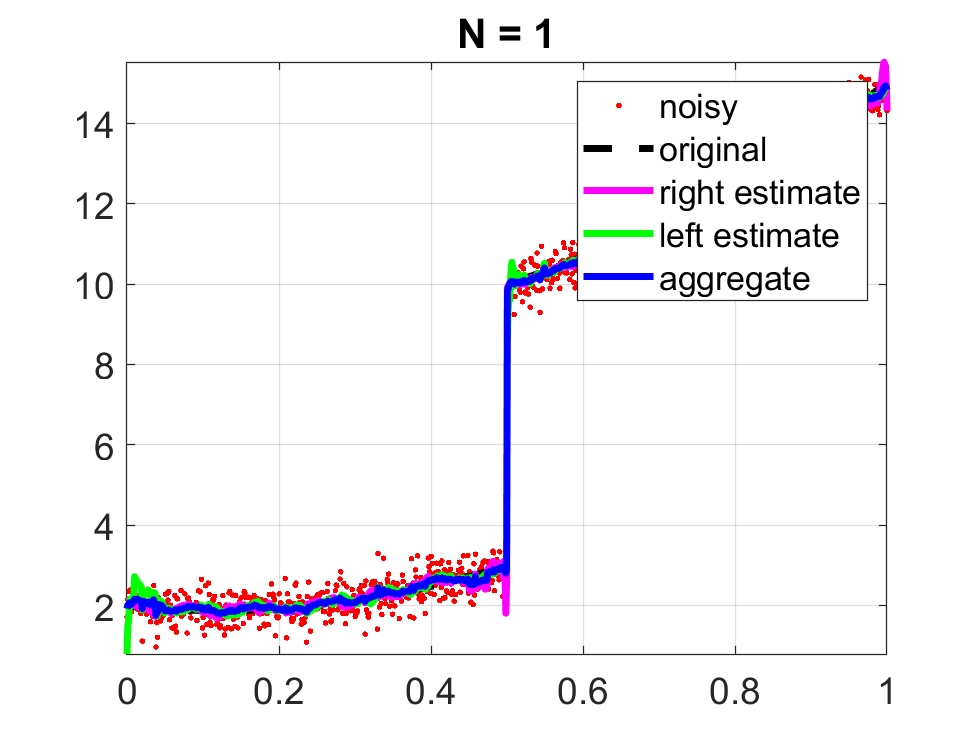

%% aggregation

% initialize the vectors for the aggregated estimate and  the variances of
% each sample (of left and right estimates)
var_left= zeros(size(s));
var_right= zeros(size(s));
for n=1:LENGTH
    % compute the estimates of the variances for sample n (use the
    % best_scale vactors)
    var_right(n) = (sigma*norm(all_g_right{best_scale_right(n)},2))^2;
    var_left(n) = (sigma*norm(all_g_left{best_scale_left(n)},2))^2;
end

% perform the aggregation
s_aggr = (s_right./var_right + s_left./var_left)./(1./var_right + 1./var_left);

figure(3), 
plot(ty, s, 'r.');
hold on
plot(ty, y, 'k--', 'LineWidth', 3);
plot(ty, s_right, 'm-','LineWidth', 3);
plot(ty, s_left, 'g-','LineWidth', 3);
plot(ty, s_aggr, 'b-','LineWidth', 3);
hold off
grid on
axis tight
title(['N = ', num2str(N)])
set(gca,'FontSize', FNT_SZ)
legend('noisy', 'original', 'right estimate', 'left estimate', 'aggregate');